# 適応アルゴリズム比較

## 基本

fleng     = 20;     %タップ数
ssize     = 0.05;   %ステップサイズ
fsize     = 2500;    %フレームサイズ
NI        = 1;     %イテレータ

plotf = 0;

## LMSフィルタの設計

lmsfilt = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',ssize);

## NLMSフィルタの設計

nlmsfilt = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',ssize);

## APフィルタの設計

po = 2;    %次元数
apfilt = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',0.5 ,'ProjectionOrder', po);

## RLSフィルタの設計

FF = 0.98;  
rlsfilt = dsp.RLSFilter(fleng, 'ForgettingFactor', FF);

## ノイズの生成

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
pinkn = Hp();
if plotf == 1
    plot(pinkn);
end
Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
whiten = Hw();
if plotf == 1
    plot(whiten);
end

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

TS1 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','LMS');
TS2 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','NLMS');
TS3 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','AP');
TS4 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','RLS');
TSe = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'LMS', 'NLMS', 'AP', 'RLS'},'Title','Err');

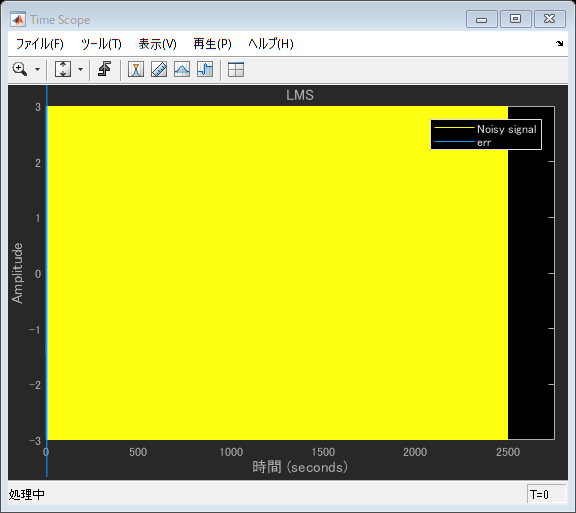

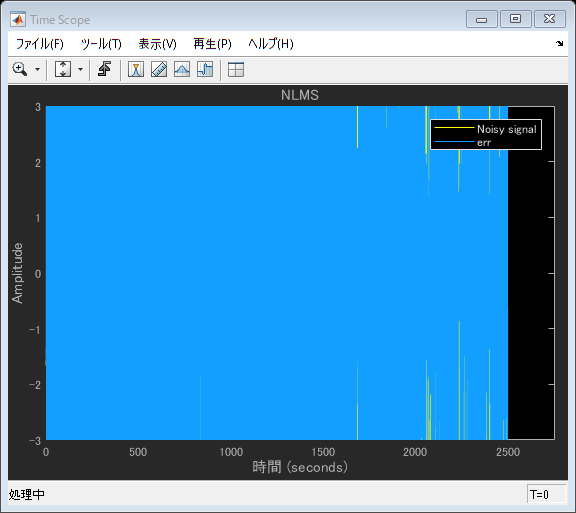

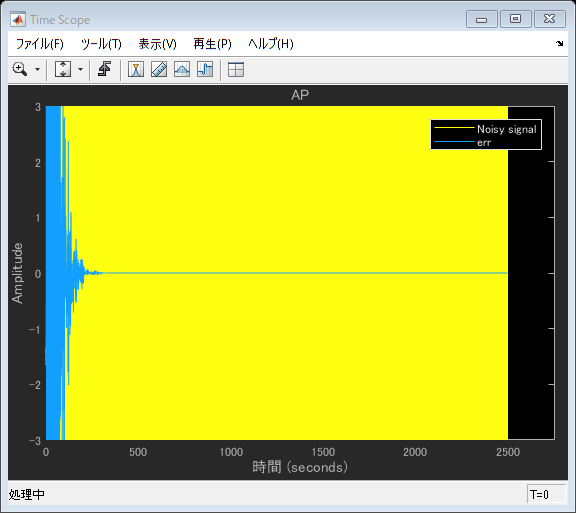

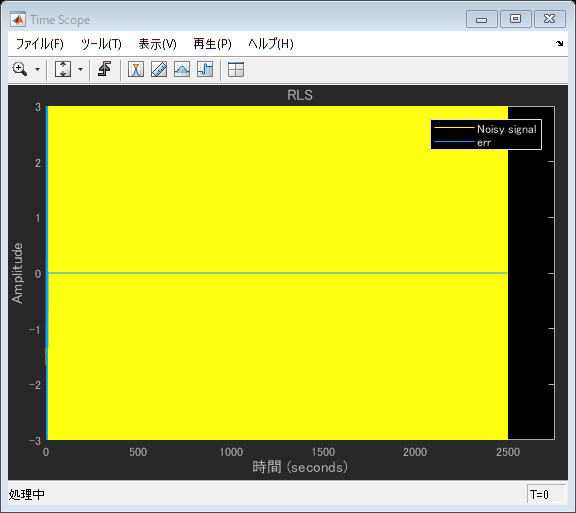

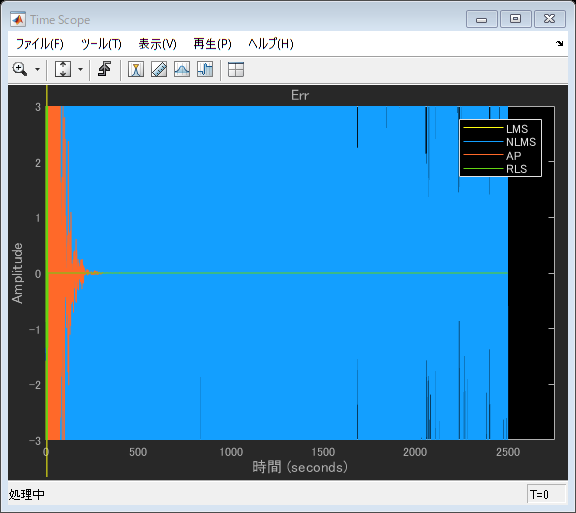

for i = 1:NI
    d = Hp()*100;
    x = firfilt(d);
    [~,e1] = lmsfilt(d,x);
    TS1([x,e1]);
    [~,e2] = nlmsfilt(d,x);
    TS2([x,e2]);
    [~,e3] = apfilt(d,x);
    TS3([x,e3]);
    [~,e4] = rlsfilt(d,x);
    TS4([x,e4]);
    TSe([e1,e2,e3,e4]);
end